# example for importance sampling of rendering equation (Cook–Torrance model)

モンテカルロ積分に使う乱数の数は `nMCint`

`それを nMC `回行って平均と分散を計算し，plotする．（ややこしい）

一応，SRPの計算にも対応（ただし太陽定数とかをかけていない）

clc
clear
cls

format long

## Monte-Carlo condition & pre-allocation

nMC = 100;

srpTrue = zeros(nMC, 3);
srpImp = zeros(nMC, 3);

## Cook–Torrance model

sat.F0 = 0.5

sat = フィールドをもつ struct :
    F0: 0.500000000000000


sat.mCT = 0.3;


### normal vector

% sat.normal = [ 0 0 1 ]; 
sat.normal = rand(1,3);
sat.normal = sat.normal ./ vecnorm(sat.normal,2,2)

sat = フィールドをもつ struct :
        F0: 0.500000000000000
       mCT: 0.300000000000000
    normal: [0.696409420356347 0.512186699201015 0.502671567129578]



sat.rho = 0.5;
sat.area = 1;

thetaI = deg2rad(60);
phiI = deg2rad(80);

sunB = [sin(thetaI)*cos(phiI), sin(thetaI)*sin(phiI), cos(thetaI)];
sunB = sunB ./ norm(sunB);

% sunB = [ -0.573721081964441   0.434806422007045   0.694109138025847]

% Monte-Carlo integration condition
nMCintUni = [100, 500, 1000, 5000, 10000, 50000, 100000];

tic
for i = 1:length(nMCintUni)
    N = nMCintUni(i);
    for j = 1:nMC

## speuclar only, uniform distribution

        % sampling for sphere region(全球) (note: not hemisphere!)
        thetaR = pi .* rand(N,1); % Nx1
        phiR = 2 * pi .* rand(N,1);

        v = [sin(thetaR).*cos(phiR) sin(thetaR).*sin(phiR) cos(thetaR)]; %Nx3       
        h = sunB + v;
        h = h ./ vecnorm(h,2,2); % bisector vector, Nx3
        thetaH = acos(h(:,3)); % Nx1
        thetaH = acos(sat.normal*h')';        

        VH = dot(v, h, 2)'; % 1xN
        NV = sat.normal * v'; % nxN, 列が各reference vector, vの値
        NS = sat.normal * sunB'; % nx1
        NH = sat.normal * h'; % nxN
        D = exp(-(tan(thetaH')./sat.mCT).^2); % Beckmann distribution, nxN        
        D = D ./ pi ./ sat.mCT.^2 ./ cos(thetaH').^4;        
        %     D = exp(-(thetaH ./ sat.mCT).^2); % Gaussian distribution, nxN

        nest = (1 + sqrt(sat.F0)) ./ (1 - sqrt(sat.F0)); % nx1
        g = sqrt(nest.^2 + VH.^2 - 1); % nxN

        temp1 = 2 * NH .* NV ./ VH; % nxN
        temp2 = 2 * NH .* NS ./ VH; % nxN
        G = min(1, temp1);
        G = min(G, temp2); % nxN

        temp1 = (g - VH).^2 / 2 ./ (g + VH).^2;
        temp2 = (1 + (VH .* (g + VH) - 1).^2 ./ (VH .* (g - VH) + 1).^2);
        F = temp1 .* temp2; % nxN

        temp = D .* G .* F ./ NS ./ NV / 4; % nxN
        temp = temp .* NV .* sin(thetaR)'; % nxN

        % for SRP
        csCTx = NS .* (NS > 0) .* (NV > 0) .* temp .* v(:,1)'; % nxN matrix
        csCTy = NS .* (NS > 0) .* (NV > 0) .* temp .* v(:,2)'; % nxN matrix
        csCTz = NS .* (NS > 0) .* (NV > 0) .* temp .* v(:,3)'; % nxN matrix

        % % for rendering eq.
        csCTx = (NS > 0) .* (NV > 0) .* temp;
        csCTy = (NS > 0) .* (NV > 0) .* temp;
        csCTz = (NS > 0) .* (NV > 0) .* temp;

        % probability
        pCT = 1 / pi * 1 / (2 * pi); % scalar

        % specular component, nx3
        srpCs = [sum(csCTx, 2), sum(csCTy, 2), sum(csCTz, 2)];
        srpCs = srpCs ./ pCT ./ N;

        srpTrue(j,:) = srpCs;
    end
    stdTrue(i,:) = std(srpTrue);
    meanTrue(i,:) = mean(srpTrue);
end
toc

経過時間は 1.889894 秒です。


## importance sampling

% Monte-Carlo integration condition
nMCintImp = [100 10^4];
nMCintImp = nMCintUni;

eAngle = acos(sat.normal(:,3));
eAxis = cross([0 0 1], sat.normal) .* (eAngle > 1e-5) ...
     + [0 0 1] * (eAngle < 1e-5);
eAxis = eAxis ./ vecnorm(eAxis, 2, 2);

qlb = [eAxis.*sin(eAngle/2), cos(eAngle/2)];

sLocal = qRotation(4, sunB, qlb);
nLocal = qRotation(4, sat.normal, qlb)

nLocal =    0.000000000000000                   0   1.000000000000000




tic
for i = 1:length(nMCintImp)
    N = nMCintImp(i);
    for j = 1:nMC
        u1 = rand(N,1);

        thetaH = atan(sqrt(-sat.mCT.^2 .* log(u1))); % Nx1
        phiH = 2 * pi .* rand(N,1);

        h = [sin(thetaH).*cos(phiH) sin(thetaH).*sin(phiH) cos(thetaH)]; %Nx3
        % h = qRotation(4, h, repmat(qlb,N,1));
        v = 2 * (h * sLocal') .* h - sLocal; % Nx3

        VH = dot(v, h, 2)'; % 1xN
        NV = nLocal * v'; % nxN, 列方向にreference vector, vの値
        NS = nLocal * sLocal'; % nx1
        NH = nLocal * h'; % nxN
        SH = (h * sLocal')'; % 1xN

        nest = (1 + sqrt(sat.F0)) ./ (1 - sqrt(sat.F0)); % nx1
        g = sqrt(nest.^2 + VH.^2 - 1); % nxN

        temp1 = 2 * NH .* NV ./ VH; % nxN
        temp2 = 2 * NH .* NS ./ VH; % nxN
        G = min(1, temp1);
        G = min(G, temp2); % nxN

        temp1 = (g - VH).^2 / 2 ./ (g + VH).^2;
        temp2 = (1 + (VH .* (g + VH) - 1).^2 ./ (VH .* (g - VH) + 1).^2);
        F = temp1 .* temp2; % nxN

        % weight
        W = abs(SH) .* G ./ NS ./ NH;

        temp = W .* F ; % nxN

        % for SRP
        % csCTx = NS .* (NS > 0) .* (NV > 0) .* temp .* v(:,1)'; % nxN matrix
        % csCTy = NS .* (NS > 0) .* (NV > 0) .* temp .* v(:,2)'; % nxN matrix
        % csCTz = NS .* (NS > 0) .* (NV > 0) .* temp .* v(:,3)'; % nxN matrix
        % srpCs = [mean(csCTx), mean(csCTy), mean(csCTz)];
        % srpCs = qRotation(4, srpCs, qInv(4, qlb));        

        % for rendering eq.
        csCTx = (NS > 0) .* (NV > 0) .* temp ;
        csCTy = (NS > 0) .* (NV > 0) .* temp ;
        csCTz = (NS > 0) .* (NV > 0) .* temp ;
        srpCs = [mean(csCTx), mean(csCTy), mean(csCTz)];
        

        srpImp(j,:) = srpCs;
    end
    stdImp(i,:) = std(srpImp);
    meanImp(i,:) = mean(srpImp);
end

toc

経過時間は 1.152523 秒です。


## show FIgs

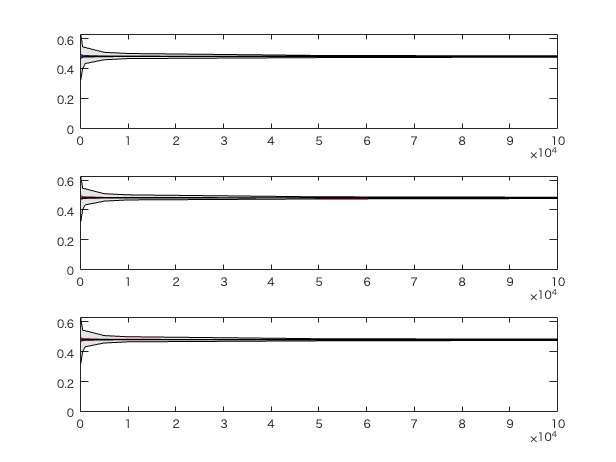

figure
tiledlayout(3,1), nexttile
plotStd(nMCintUni, meanTrue(:,1), stdTrue(:,1), 'r'), hold on
plotStd(nMCintImp, meanImp(:,1), stdImp(:,1), 'b', 'b');


nexttile
plotStd(nMCintUni, meanTrue(:,2), stdTrue(:,2)); hold on
plotStd(nMCintImp, meanImp(:,2), stdImp(:,2),'b', 'b');

nexttile
plotStd(nMCintUni, meanTrue(:,3), stdTrue(:,3)); hold on
plotStd(nMCintImp, meanImp(:,3), stdImp(:,3), 'b', 'b');

### mean and standard deviation

[meanTrue(end,:)
    meanImp(end,:)]

ans =    0.480187691555994   0.480187691555994   0.480187691555994
   0.480926504590384   0.480926504590384   0.480926504590384



[norm(meanTrue(end,:))
    norm(meanImp(end,:))]

ans =    0.831709478944194
   0.832989140657051
